clc;        %per pulire la command windows
clear;      %per pulire tutte le variabbili
close all;  %per chiudere tutte le finestre aperte



# **MANIPOLATORE PLANARE A DUE BRACCI **

### Dati

P=zeros(1,2);
P=[1.5 1];                              % punto di partenza

A=zeros(1,2);
A=[1 1.2];                              % punto di arrivo

param=zeros(1,9);
param(1,1)=1;                           % massa braccio 1
param(1,2)=1;                           % massa braccio 2
param(1,3)=1;                           % lunghezza braccio 1
param(1,4)=1;                           % lunghezza braccio 2
param(1,5)=0.5;                         % distanza del baricentro del braccio 1 dall'asse del giunto
param(1,6)=0.5;                         % distanza del baricentro del braccio 1 dall'asse del giunto
param(1,7)=1;                           % inerzia braccio 1
param(1,8)=1;                           % inerzia braccio 2
param(1,9)=9.81;                        % accelerazione gravitazionale


#### Estraggo i valori degli angoli e delle posizioni dei giunti dalla funzione get_theta

[theta1P,theta2P,theta1A,theta2A,O,C1,C2,P1,A1] = get_theta(P,A,param);

### Visualizzazione delle due configurazioni

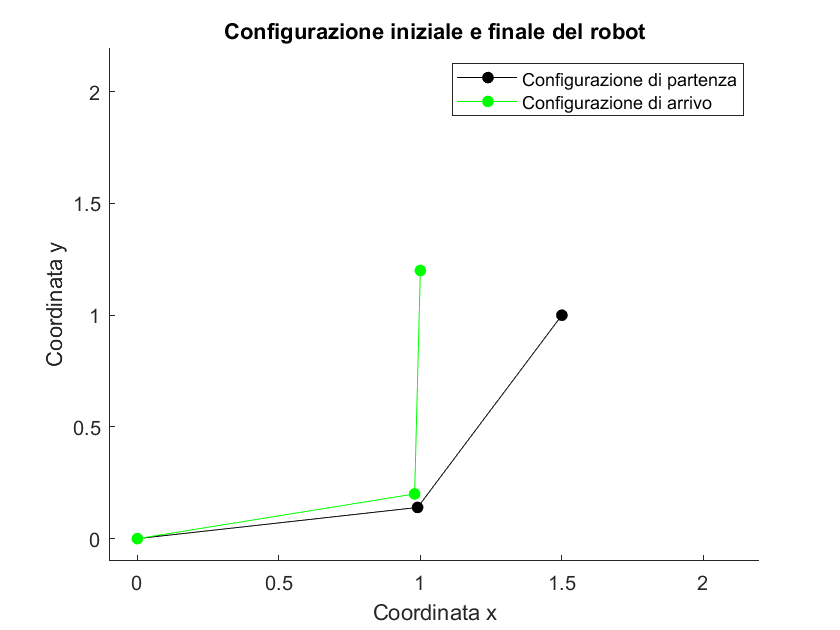

figure
line([O(1,1),C1(1,1),P1(1,1)],[O(2,1),C1(2,1),P1(2,1)],'Color','Black','Marker','.','MarkerSize',20)
hold on
line([O(1,1),C2(1,1),A1(1,1)],[O(2,1),C2(2,1),A1(2,1)],'Color','Green','Marker','.','MarkerSize',20)
xlim([-0.1 param(1,3)+param(1,4)+0.2])
ylim([-0.1 param(1,3)+param(1,4)+0.2])
title('Configurazione iniziale e finale del robot')
legend('Configurazione di partenza','Configurazione di arrivo','Location','northeast')
xlabel('Coordinata x')
ylabel('Coordinata y')
hold off

#### Posizioni dei moventi iniziali e finali e velocità iniziale

q=[theta1P;theta2P]                     % Posizione dei moventi iniziale

q =     0.1402
    0.8957


qA=[theta1A;theta2A]                    % Posizione dei moventi finale

qA =     0.2016
    1.3490


dq0=[0;0];                              % Velocità iniziale

### Regolatore PD

f=100;                                  % Frequenza del controllore
dt=1/f;                                 % Frequenza temporale' del controllore
Kp=10;                                  % Parametro proporzionale regolatore
Kd=5;                                   % Costante derivativa
tau=[0;0];                              % Forza esterna
maxindex=1000;                          % Masssime iterate prima che il codice si fermi senza aver trovato una soluzione

### Raggiungimento della configurazione finale

[qE,yE] = Eulero(q,qA,param,dt,Kp,Kd,tau,maxindex)   %Tramite la funzione 'Eulero' trovo la posizione finale e la "storia" del percorso fatto dal robot

qE =     0.2062
    1.3510


yE =     0.1399    0.8963
    0.1395    0.8976
    0.1389    0.8994
    0.1381    0.9016
    0.1372    0.9044
    0.1361    0.9075
    0.1349    0.9110
    0.1337    0.9148
    0.1323    0.9189
    0.1309    0.9233


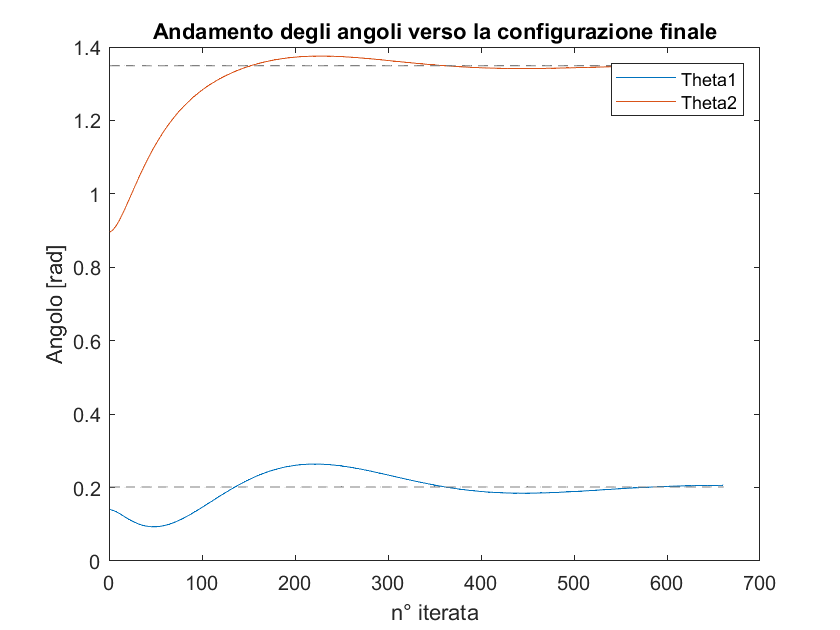


figure                                  % Plotto la "storia" dei valori degli angoli raggiunti prima di arrivare alla configurazione voluta
plot(yE)
hold on
plot(repmat(qA,1,length(yE))','color',[0.5 0.5 0.5],'LineStyle','--')
title('Andamento degli angoli verso la configurazione finale')
legend('Theta1','Theta2','Location','northeast')
xlabel('n° iterata')
ylabel('Angolo [rad]')
hold off

### Computed torque

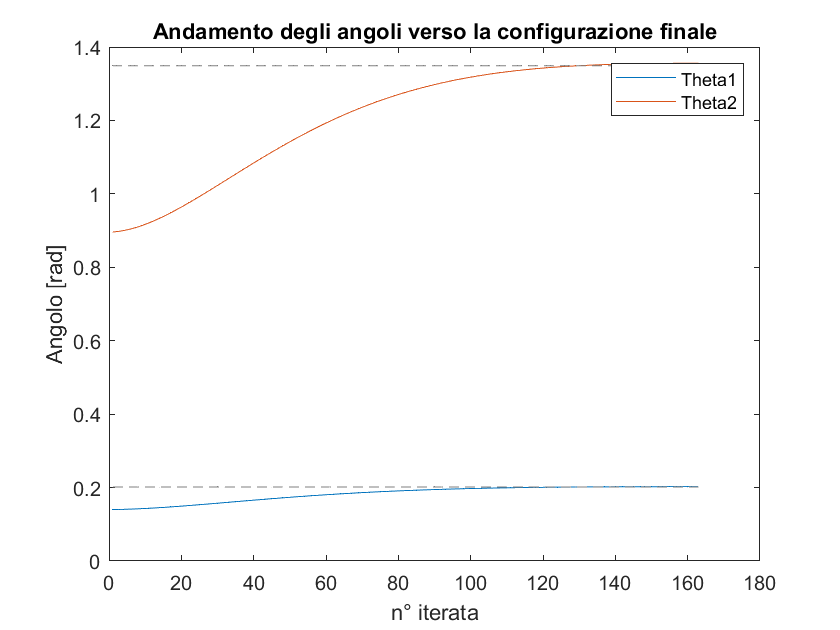

[qCT,yCT] = Computed_torque(q,qA,param,dt,Kp,Kd,tau,maxindex);

figure                                  % Plotto la "storia" dei valori degli angoli raggiunti prima di arrivare alla configurazione voluta
plot(yCT)
hold on
plot(repmat(qA,1,length(yCT))','color',[0.5 0.5 0.5],'LineStyle','--')
title('Andamento degli angoli verso la configurazione finale')
legend('Theta1','Theta2','Location','northeast')
xlabel('n° iterata')
ylabel('Angolo [rad]')
hold off

### Modellazione della superficie

#### Posizione della parete

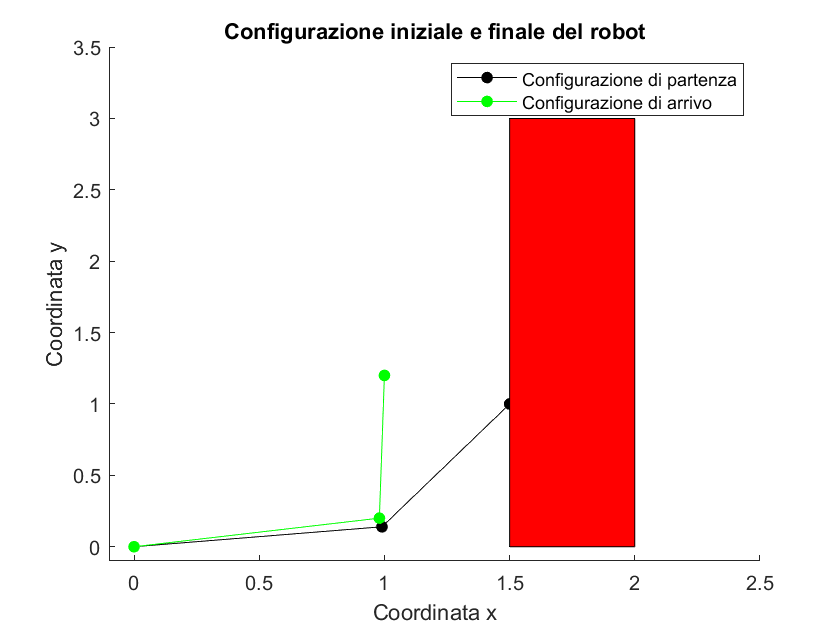

figure
line([O(1,1),C1(1,1),P1(1,1)],[O(2,1),C1(2,1),P1(2,1)],'Color','Black','Marker','.','MarkerSize',20)
hold on
line([O(1,1),C2(1,1),A1(1,1)],[O(2,1),C2(2,1),A1(2,1)],'Color','Green','Marker','.','MarkerSize',20)
axis([-0.1 2.5 -0.1 3.5])
title('Configurazione iniziale e finale del robot')
legend('Configurazione di partenza','Configurazione di arrivo','Location','northeast')
xlabel('Coordinata x')
ylabel('Coordinata y')
rectangle('Position',[1.5 0 0.5 3],'FaceColor','Red')
hold off

#### Modellazione della forza di contatto con la parete

k=1000;             %costante elastica della parete
fext=k*dx

### Energia del sistema

W=1/2*transpose(dq)*B*dq

Unrecognized function or variable 'dq'.